# Train deepGLM for DirectMarketing Data

Load DirectMarketing dataset. The data has following information:

- Training data: 900 observations

- Testing data: 100 observations

- Number of covariates: 10

clear
clc
load('../Data/DirectMarketing.mat')

## **Training Phase**

Now start training deepGLM with some settings. By default, if **'distribution'** option is not specified then deepGLMfit will treat y as continuous responses

nn = [5,5];
lb = true;
mdl = deepGLMfit(X,y,...          
                 'Network',nn,... 
                 'Lrate',0.01,...           
                 'Verbose',10,...             % Display training result each iteration
                 'BatchSize',size(X,1),...   % Use entire training data as mini-batch
                 'MaxEpoch',10000,...
                 'Patience',50,...           % Higher patience values could lead to overfitting
                 'Lowerbound',lb,...         % Use lowerbound as early stopping condition and model selection
                 'Seed',100);

Initial LB: -2.835
---------- Training Phase ----------
Epoch: 9   -   Current LB: -2.2324
Epoch: 19   -   Current LB: -2.1807
Epoch: 29   -   Current LB: -2.1808
Epoch: 39   -   Current LB: -2.1699
Epoch: 49   -   Current LB: -2.1604
Epoch: 59   -   Current LB: -2.1508
Epoch: 69   -   Current LB: -2.1404
Epoch: 79   -   Current LB: -2.1293
Epoch: 89   -   Current LB: -2.118
Epoch: 99   -   Current LB: -2.1061
Epoch: 109   -   Current LB: -2.0927
Epoch: 119   -   Current LB: -2.0782
Epoch: 129   -   Current LB: -2.0636
Epoch: 139   -   Current LB: -2.0476
Epoch: 149   -   Current LB: -2.0293
Epoch: 159   -   Current LB: -2.0093
Epoch: 169   -   Current LB: -1.9873
Epoch: 179   -   Current LB: -1.9627
Epoch: 189   -   Current LB: -1.9372
Epoch: 199   -   Current LB: -1.9122
Epoch: 209   -   Current LB: -1.8878
Epoch: 219   -   Current LB: -1.8658
Epoch: 229   -   Current LB: -1.8435
Epoch: 239   -   Current LB: -1.8222
Epoch: 249   -   Current LB: -1.8012
Epoch: 259   -   Current LB: -1

Now plot convergence curve of lowerbound during training phase.

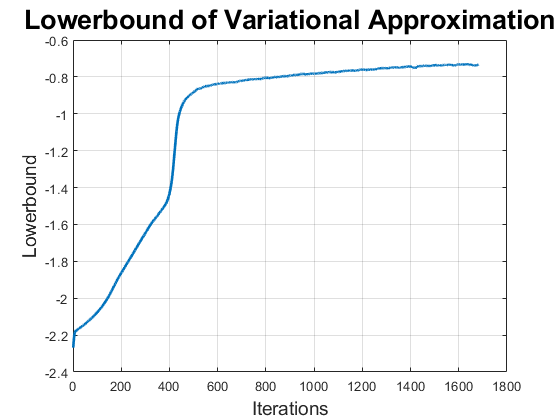

figure
plot(mdl.out.lbBar,'LineWidth',2)
title('Lowerbound of Variational Approximation','FontSize',20)
xlabel('Iterations','FontSize',14,'FontWeight','bold')
ylabel('Lowerbound','FontSize',14,'FontWeight','bold')
grid on

## **Variable selection**

Now plot Shrinkage coefficients to show if adatptive group Lasso can perform variable selection efficiently.

Specify shrinkage option to plot shrinkage coefficient from training phase

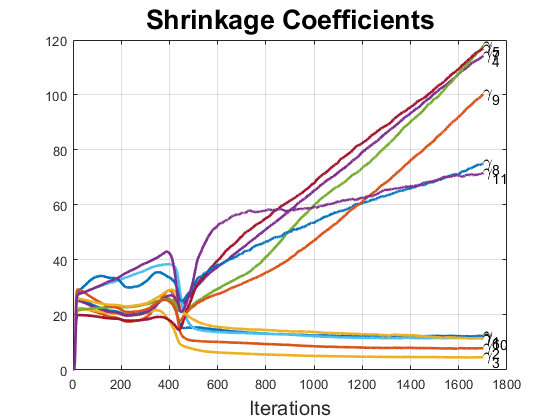

deepGLMplot('Shrinkage',mdl.out.shrinkage,...     % Plot Shrinkage coefficients
            'Title','Shrinkage Coefficients',...
            'Xlabel','Iterations',...
            'LineWidth',2);

The shrinkage coefficients of variables **4,5,7,8,9,11** significantly higher than the others at the end of training phase. 

So  these variables are not important in the model.

Now let's check if linear regression model gives us the same results on variable selection

Now let's check if linear regression model gives us the same results on variable selection

mdlOLS = fitglm(X,y)

mdlOLS = Generalized linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11
    Distribution = Normal

Estimated Coefficients:
                   Estimate        SE        tStat        pValue  
                   _________    ________    ________    __________

    (Intercept)       1.2083    0.016228      74.459             0
    x1              -0.20185    0.019185     -10.521    1.7685e-24
    x2               0.27858    0.017178      16.217    5.3457e-52
    x3               0.63694    0.032713       19.47    1.3714e-70
    x4              0.010944    0.017371     0.63004       0.52883
    x5             -0.017643    0.023582    -0.74813       0.45458
    x6              -0.21175    0.017007    

p-values of variables 4,5,7,8,9,11 are much higher than the others

This variable selection result perfectly matches with **deepGLM**

## Prediction 

The next step is to make prediction from trained model. deepGLM provide point and interval estimation for unseen data. 

In order to make point estimation for new data, use **deepGLMpredict** function. **deepGLMpredict** outputs an array of point estimations of observations in test data

Pred1 = deepGLMpredict(mdl,X_test);

If responses for test data (ytest) is specified (for model evaluation purpose) then we can check PPS and MSE on test set. Specify test data with option **'ytest'. **The output of **deepGLMpredict** is a structure including:

- An array of prediction values for each observation in test data

- PSS loss of test data

- MSE of test data

Pred2 = deepGLMpredict(mdl,X_test,'ytest',y_test);
disp(['PPS on test set using deepGLM is: ',num2str(Pred2.pps)])

PPS on test set using deepGLM is: -0.17324


disp(['MSE on test set using deepGLM is: ',num2str(Pred2.mse)])

MSE on test set using deepGLM is: 0.25196


**deepGLM** also provides prediction interval option. 

In order to make interval estimation, specify the interval (within how many std) for option **'Interval'** in the function **deepGLMpredict. **

 Provide sampe size using **'Nsample'** options.

Pred4 = deepGLMpredict(mdl,X_test,...  
                      'Interval',1,...  % Give prediction interval within 1 std from mean for each new observation
                      'Nsample',1000);  % Number of samples generated from VB Posterior distribution of weigths                 

% Calculate how many percent of times that the prediction invertals are correct
accuracy = (y_test<Pred4.interval(:,2) & y_test>Pred4.interval(:,1));
disp(['Prediction Interval accuracy: ',num2str(sum(accuracy)/length(accuracy))]);

Prediction Interval accuracy: 0.78


Now we can plot the prediction interval for a subset of unseen data points. Specify **'interval'** option for **deepGLMplot**

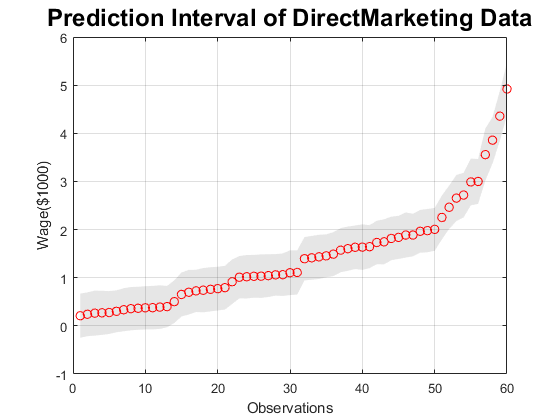

figure
deepGLMplot('Interval',...                 % Plot prediction intervals
             Pred4,...
            'Title','Prediction Interval of DirectMarketing Data',...
            'Xlabel','Observations',...
            'Ylabel','Wage($1000)',...
            'Nsample',60);                 % Randomly pick 60 observations to plot

If we want to plot the true responses, the specify true response vector for the option **'ytest'**

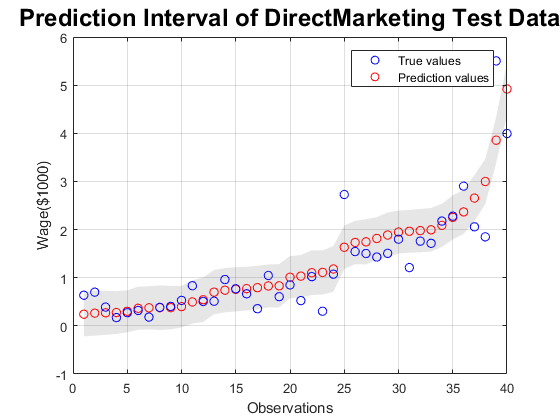

figure
deepGLMplot('Interval',...
             Pred4,...
            'ytest',y_test,...              % Plot true responses
            'Title','Prediction Interval of DirectMarketing Test Data',...
            'Xlabel','Observations',...
            'Ylabel','Wage($1000)',...
            'Nsample',40);                  % Randomly pick 40 new observations to plot